clear all;
clc;

% Carregar os dados
Input1 = load("Input1.mat");
Input1 = Input1.Input1';

Input2 = load("Input2.mat");
Input2 = Input2.Input2';

Output = [zeros(2000, 1)+1; ones(2000, 1)+1]; % Definir rótulos de classe 1 e 2


# `Aplicação ``K-fold`` nas bases de dados`

K = 10; 
[acc, std] = k_fold_validation(Input1, Output, K);
fprintf(['Base de dados: Input1 ' ...
    '\nAcurácia Média - Bayes: %.2f %% ' ...
    '\nAcurácia Média - LDA: %.2f %% ' ...
    '\nDesvio padrão das acurácias - Bayes: %.4f ' ...
    '\nDesvio padrão das acurácias - LDA: %.4f'], acc*100, std);

Base de dados: Input1 
Acurácia Média - Bayes: 100.00 % 
Acurácia Média - LDA: 100.00 % 
Desvio padrão das acurácias - Bayes: 0.0000 
Desvio padrão das acurácias - LDA: 0.0000

[acc, std] = k_fold_validation(Input2, Output, K);
fprintf(['Base de dados: Input2 ' ...
    '\nAcurácia Média - Bayes: %.2f %% ' ...
    '\nAcurácia Média - LDA: %.2f %% ' ...
    '\nDesvio padrão das acurácias - Bayes: %.4f ' ...
    '\nDesvio padrão das acurácias - LDA: %.4f'], acc*100, std);

Base de dados: Input2 
Acurácia Média - Bayes: 85.47 % 
Acurácia Média - LDA: 50.43 % 
Desvio padrão das acurácias - Bayes: 0.0149 
Desvio padrão das acurácias - LDA: 0.0297

class_data1 = separar_por_classe(Input1, Output); % Separação das classes na base de dados Input1
class_data2 = separar_por_classe(Input2, Output); % Separação das classes na base de dados Input2

`Gráfico de Dispersão das classes`` para o banco de dados ``Input1`

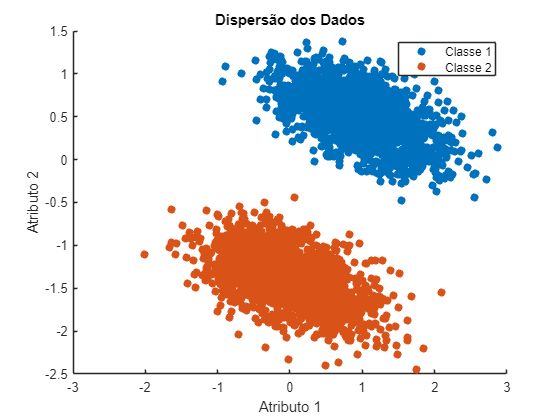

plotDispersao(class_data1);

`Gráfico de Dispersão das classes`` para o banco de dados ``Input2`

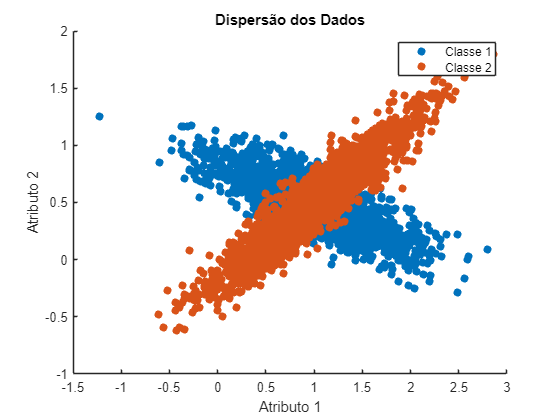

plotDispersao(class_data2);

`Gráfico de Dispersão Gaussiano`` para o banco de dados ``Input1`

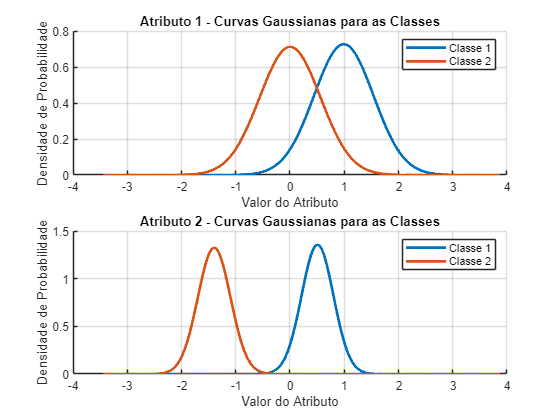

plotCurvasGaussianas(class_data1, Input1);

`Gráfico de Dispersão Gaussiano`` para o banco de dados ``Input2`

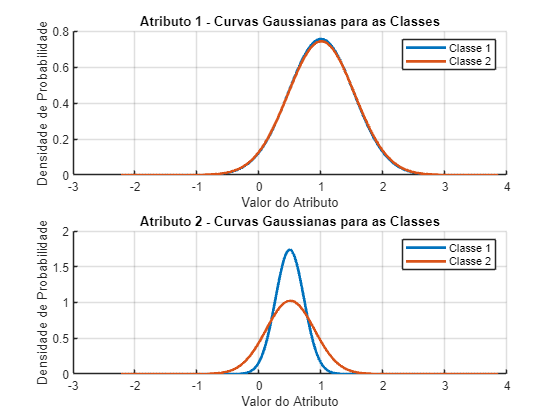

plotCurvasGaussianas(class_data2, Input2);

# `Análise sobre o desempenho das bases de dados`

`No primeiro banco de dados, Input1, temos uma distribuição dos dados bem comportada em relação às classes, permitindo uma separação visual clara entre elas, com os centróides de cada classe bem separados visualemente. Por outro lado, no Input2, a dispersão das classes se cruza, resultando em médias de ambas as classes muito próximas. Essa característica evidencia a principal limitação do LDA, justificando o baixo desempenho quando aplicado ao Input2. Como consequência, as distribuições gaussianas das classes em Input2 tornam-se muito semelhantes para ambos os atributos, o que também faz com que o desempenho do classificador Bayesiano diminua em comparação ao Input1.`

`K-fold`

function [accuracia, desvio_padrao] = k_fold_validation(Input, Output, K)
    indices = crossvalind('Kfold', Output, K);
    accuracy = zeros(K, 2);
    
    for k = 1:K
        test_idx = (indices == k);
        train_idx = ~test_idx;
        train_x = Input(train_idx, :);
        train_y = Output(train_idx);
        test_x = Input(test_idx, :);
        test_y = Output(test_idx);
        
        % Classificação Bayesiana
        previsao_bayes = bayesian_classifier(train_x, train_y, test_x);
        
        % Classificação LDA
        [previsao_LDA, ~] = lda_classifier(train_x, train_y, test_x);
        
        % Calcular acurácia para cada classificador
        accuracy(k, 1) = sum(previsao_bayes == test_y) / length(test_y);
        accuracy(k, 2) = sum(previsao_LDA == test_y) / length(test_y);
    end
    
    accuracia = mean(accuracy);
    desvio_padrao = std(accuracy);
end


`Classificador Bayesiano`

function previsao_bayes = bayesian_classifier(train_x, train_y, test_x)
    % Separar os dados por classe
    class_data = separar_por_classe(train_x, train_y);
    
    % Calcular média (u) e covariância (C) para cada classe
    [u, ~, C] = calculateMuSigmaCov(class_data);
    
    % Inicializar matriz de probabilidades a posteriori
    posteori = zeros(length(test_x), length(class_data));
    
    for i = 1:length(class_data)
        % Prior para a classe i
        p = length(class_data{i}) / length(train_y);
        for j = 1:length(test_x)
            % Calcular probabilidade a posteriori usando Gaussiana multivariada
            posteori(j, i) = p * multivariate_gaussian(test_x(j,:)', u(:,i), C{i});
        end
    end
    
    % Prever classe com maior probabilidade a posteriori
    [~, previsao_bayes] = max(posteori, [], 2);
end

`LDA -  Classificador Unidimensional Baseado em Limiar`

function [previsao_LDA, w] = lda_classifier(train_x, train_y, test_x)
    % Separar os dados por classe
    class_data = separar_por_classe(train_x, train_y);
    
    % Calcular média (u) e covariância (C) para cada classe
    [u, ~, C] = calculateMuSigmaCov(class_data);
    
    % Calcular matriz de covariância dentro das classes (Sw)
    Sw = C{1} + C{2};

    % Calcular matriz de covariância entre classes (Sb)
    Sb = (u(:,1) - u(:,2)) * (u(:,1) - u(:,2))';
    
    % Calcular autovetores e autovalores
    [V, D] = eig(Sw \ Sb);
    [~, id] = max(diag(D));
    w = V(:, id);
    w = w / norm(w);
    
    % Calcular limiar
    limiar = (u(:,1)' + u(:,2)')/2 * w;

    % Prever classes com base no limiar
    previsao_LDA = (test_x * w >= limiar) + 1;
end

`Função de cálculos`

function [mu, sigma, Cov] = calculateMuSigmaCov(class_data)
    % Calcula médias (mu) e desvios padrão (sigma) para cada classe e atributo
   
    num_classes = length(class_data);
    num_attributes = size(class_data{1}, 2);
    
    mu = zeros(num_classes, num_attributes);
    sigma = zeros(num_classes, num_attributes);
    Cov = cell(num_classes,1);
    
    for i = 1:num_classes
        mu(:, i) = mean(class_data{i}, 1);
        sigma(:, i) = std(class_data{i}, 0, 1);
        Cov{i} = cov(class_data{i});
    end
end

`Separação de classes`

function class_data = separar_por_classe(Input, Output)
    classes = unique(Output);
    class_data = cell(length(classes), 1);
    % Separar os dados por classe
    for i = 1:length(classes)
        class_data{i} = Input(Output == classes(i), :);
    end
end

`Função Gaussiana Multivariada`

function f = multivariate_gaussian(x, mu, C)
    n = length(mu);
    diff = x - mu;
    % Cálculo da função Gaussiana multivariada
    f = (1 / ((2 * pi)^(n / 2) * sqrt(det(C)))) * ...
        exp(-0.5 * diff' * (C \ diff));
end

`Função Gaussiana Univariada`

function f = gaussian(x, mu, sigma)
    f = (1 / (sigma * sqrt(2 * pi))) * exp(-0.5 * ((x - mu) / sigma).^2);
end

`Função para Plotar o Gráfico de Dispersão`

function plotDispersao(class_data)
    figure;
    hold on;
    
    % Definir cores para cada classe
    num_classes = length(class_data);
    colors = lines(num_classes);
    
    % Plotar cada classe
    for i = 1:num_classes
        scatter(class_data{i}(:,1), class_data{i}(:,2), 36, colors(i, :), 'filled', 'DisplayName', sprintf('Classe %d', i));
    end
   
    xlabel('Atributo 1');
    ylabel('Atributo 2');
    title('Dispersão dos Dados');
    legend('show');
    hold off;
end


`Função para Plotar Curvas Gaussianas`

function plotCurvasGaussianas(class_data, Input1)
    % Calcular médias e desvios padrão
    [mu, sigma, ~] = calculateMuSigmaCov(class_data);
    mu = mu';
    sigma = sigma';

    % Definir o intervalo para os gráficos
    x = linspace(min(Input1(:)) - 1, max(Input1(:)) + 1, 1000);
    
    % Funções Gaussianas para cada classe e cada atributo
    y_attr = cell(size(mu, 1), size(Input1, 2));
    
    for j = 1:size(Input1, 2)
        for i = 1:size(mu, 1)
            y_attr{i, j} = gaussian(x, mu(i, j), sigma(i, j));
        end
    end

    figure;

    % Subplot para cada atributo
    for j = 1:size(Input1, 2)
        subplot(size(Input1, 2), 1, j);
        
        % Plotar curvas gaussianas para cada classe
        hold on;
        colors = lines(size(mu, 1)); 
        for i = 1:size(mu, 1)
            plot(x, y_attr{i, j}, 'Color', colors(i, :), 'LineWidth', 2, 'DisplayName', sprintf('Classe %d', i));
        end
        
        title(sprintf('Atributo %d - Curvas Gaussianas para as Classes', j));
        xlabel('Valor do Atributo');
        ylabel('Densidade de Probabilidade');
        legend('show');
        grid on;
        hold off;
    end
end